clc
clear

figure
xlim([0, 10])
ylim([0, 10])
grid("minor")
hold on

x_ship = randi(10);
y_ship = randi(10);

% Skudforsøg

x_guess = input("First X guess: ")

x_guess = 5

y_guess = input("First Y guess: ")

y_guess = 10


distance = sqrt((abs(x_guess - x_ship))^2 + abs(y_guess - y_ship)^2)

distance = 0

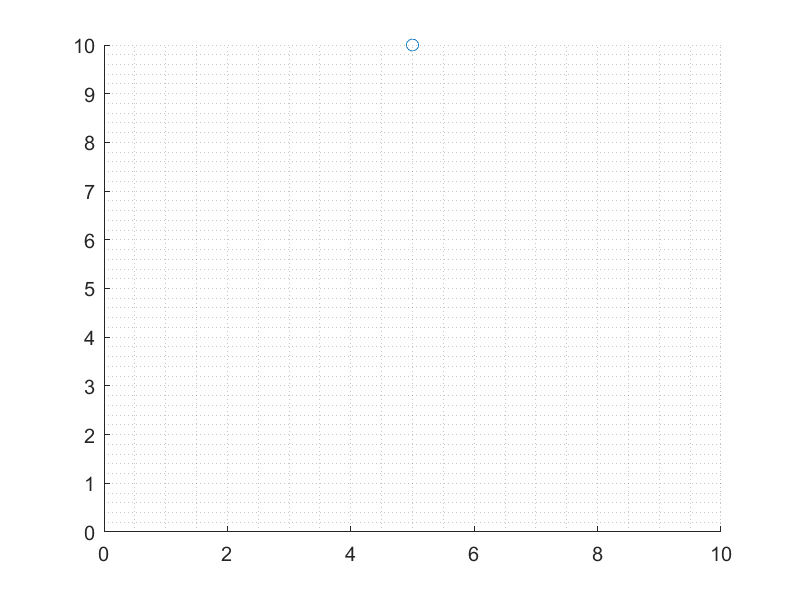


scatter(x_guess, y_guess)


drawnow()

if distance > 1
    while distance > 1
        xnew = input("New X: ");
        ynew = input("New Y: ");
        dist_new = sqrt((abs(xnew - x_ship))^2 + abs(ynew - y_ship)^2)
    
        scatter(xnew, ynew)
        drawnow()
        
        if dist_new < 1
            break
        end

    end
    
    if dist_new < 1
        fprintf("You Won!")
        scatter(x_ship, y_ship, 'xr')
        drawnow()
    end
end